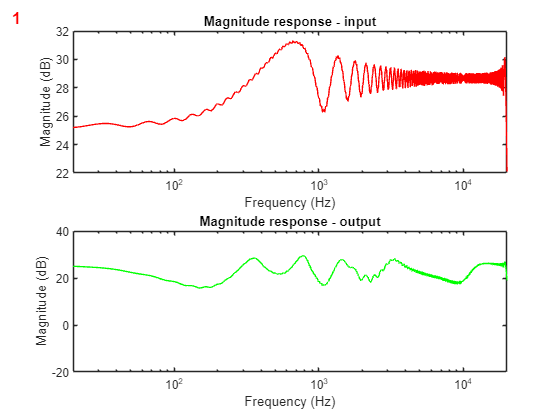

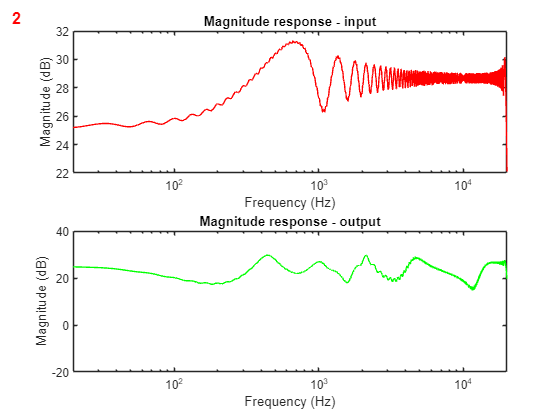

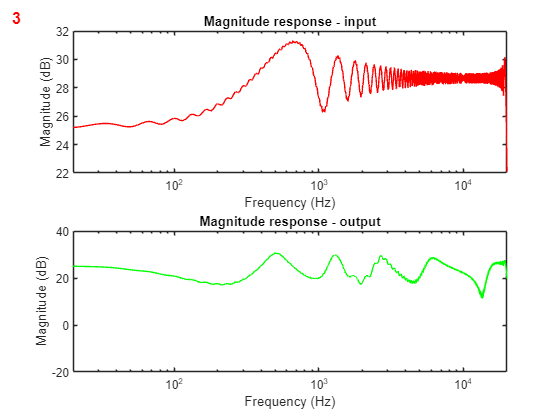

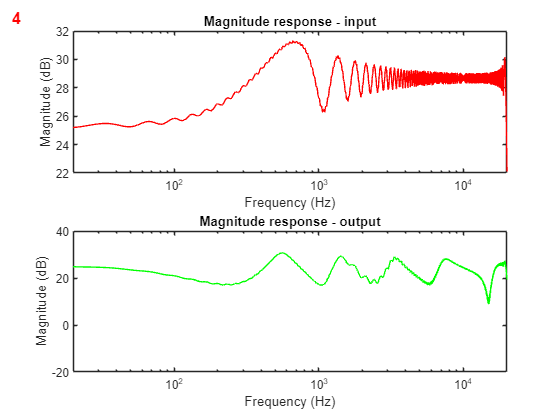

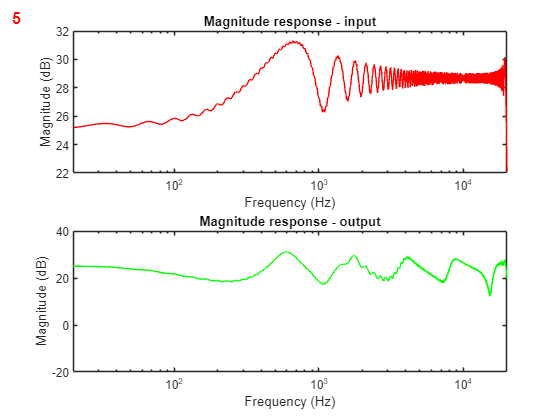

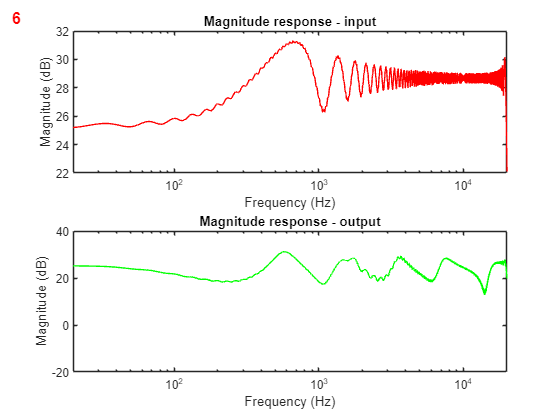

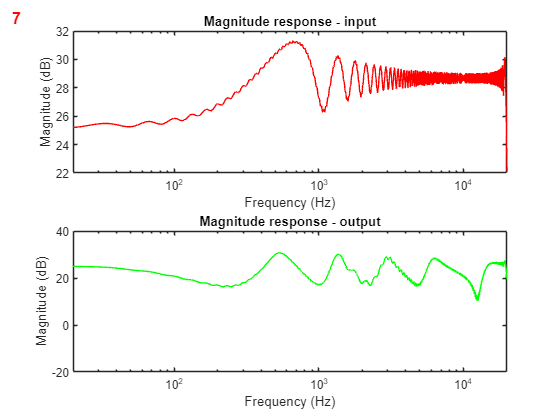

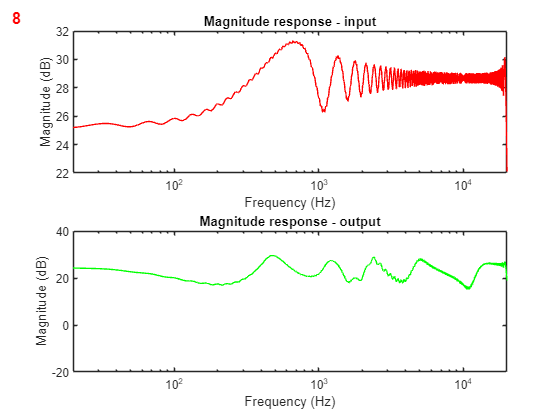

% SET FILTER PARAMETERS:
s = 100; % speed knob 1-100
lfo = 'triangle'; % 'triangle/sine'
fb_state = 'on'; % 'on/off'

% Initiate single chirp
fs = 44100;
t = 0:1/44100:1/33;
inputSignal = chirp(t,20,1/33,20000);

for k = 1:33 % index of chirp
tk = 0:1/44100:k/33;
inputSignal2 = zeros(size(tk));
for n = 1:(length(inputSignal))
    inputSignal2(n+(k-1)*length(inputSignal)) = inputSignal(n);
end

% Main phaser function:
y1 = phaser(inputSignal2, fs, s, lfo, fb_state);

% freqz
[H,w] = freqz(inputSignal2, 1, 'half', fs);
[H1,w1] = freqz(y1, 1, 'half', fs);
Hdb = mag2db(abs(H));
Hdb1 = mag2db(abs(H1));

% Plot
figure;
subplot(2,1,1);
semilogx(w/pi*fs/2, Hdb, '-r');
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)');
title('Magnitude response - input');
xlim([20,20000]);

subplot(2,1,2);
semilogx(w1/pi*fs/2, Hdb1, '-g');
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)');
title('Magnitude response - output');
ylim([-20,40]);
xlim([20,20000]);
annotation('textbox', [0.01, 0.99, 0, 0], 'String', num2str(k), 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'red');

% Save the figure with a dynamically generated file name
saveas(gcf, ['my_fig_' num2str(k) '.png']);
end

function output = phaser(input, fs, s, lfo, fb_state)
    f_lfo = 0.069 * exp(0.04*s); % f_lfo in Hz from speed(1,100)
    t = (0:length(input)-1) / fs; % time vector
    wave = mod(f_lfo, t, lfo); % takes time-vector, make lfo

    wet = allpassFilters(input, wave, fb_state); % main filtering function
    
    wet = wet/max(abs(wet)); % normalize wet
    output = 0.5 * input + 0.5 * wet; % dry + wet signal
    output = output/max(abs(output)); % normalize output
end

% Main cascaded filtering function
function output = allpassFilters(input, a, fb_state)
    if strcmp(fb_state, 'on')
        Fbgain = 0.4; % set feedback gain to 0.4
    elseif strcmp(fb_state, 'off')
        Fbgain = 0; % no feedback
    else
        error('Use ''on'' or ''off'' for feedback dummy!');
    end
    a1 = -0.89; % fixed coeff for first/last pairs
    
    stage0 = input;
    feedback = zeros(size(input));
    stage1 = zeros(size(input));
    stage2 = zeros(size(input));
    stage3 = zeros(size(input));
    stage4 = zeros(size(input));
    stage5 = zeros(size(input));
    stage6 = zeros(size(input));
    stage7 = zeros(size(input));
    stage8 = zeros(size(input));
    stage9 = zeros(size(input));
    output = zeros(size(input));

    for n = 2:length(input)
        feedback(n) = Fbgain*output(n-1);
        stage0(n) = stage0(n) + feedback(n);

        stage1(n) = a1 * stage0(n) + stage0(n-1) - a1 * stage1(n-1);
        stage2(n) = a1 * stage1(n) + stage1(n-1) - a1 * stage2(n-1);

        stage3(n) = a(n) * stage2(n) + stage2(n-1) - a(n) * stage3(n-1);
        stage4(n) = a(n) * stage3(n) + stage3(n-1) - a(n) * stage4(n-1);
        stage5(n) = a(n) * stage4(n) + stage4(n-1) - a(n) * stage5(n-1);
        stage6(n) = a(n) * stage5(n) + stage5(n-1) - a(n) * stage6(n-1);
        stage7(n) = a(n) * stage6(n) + stage6(n-1) - a(n) * stage7(n-1);
        stage8(n) = a(n) * stage7(n) + stage7(n-1) - a(n) * stage8(n-1);

        stage9(n) = a1 * stage8(n) + stage8(n-1) - a1 * stage9(n-1);
        output(n) = a1 * stage9(n) + stage9(n-1) - a1 * output(n-1);
    end
end

% LFO function, amplitude = modulating coeffs
function y = mod(f, t, lfo)
    if strcmp(lfo, 'triangle')
        y = sawtooth(2*pi*f*t, 0.5)*(0.225) - 0.615; % triangle wave [-0.84, -0.39]
    elseif strcmp(lfo, 'sine')
        y = abs(sin(2*pi*f*t/2))*(1.26) - 0.49; % full wave rectified [-0.49, 0.77]
    else
        error('Invalid LFO type. Use ''triangle'' or ''sine''.');
    end
end
